# PWM light control simulator

% consider the following: A line scan camera captures an image of an object
% illuminated by a light source, and the intensity of this light source is
% controlled by a PWM signal.

% The lines of the images might not all be equally exposed due to the
% nature of this on/off control. This may result in a strobing effect,
% where periodically lines are more and less exopsed. What happends to this
% strobing effect when the frequency of the PWM signal is increased? is
% there a way to limit or alliminate this effect?

% This simulator simulates this scenario for different PWM signals. As a
% result, two graphs are plotted. 

% The left graph shows the PWM signal of the light source as a function of
% time, as well as the time the LSC's sensor captures light as a function
% of time.

% The right graph shows the accumulated light for every line. Depending on
% the parameters, one can see that not every line will receive the same
% amount of light, which will result in the strobing effect.

% This simulator was used to contruct several graphs for my thesis, in
% which the full explenation can be found.


## Calculations

% The following variables can be changed:
freq_LSC = 10000;           % frequency of the line scan camera [Hz]
freq_line_light = 12000;    % frequency of the PWM signal of the line light [Hz]
duty_LSC = 80;              % duty cycle of the LSC (% of period in which the camera collects light)
duty_line_light = 30;       % duty cycle of line light [%]
num_periods = 3;            % number of periods shown in graphs = number of lines simulated.
time_res = 10000;           % resulution of time vector (higher=more detailed --> more computation)
offset = 30;                 % offset of PWM signal [%]

% calculate time vector
t = linspace(0, num_periods/freq_LSC, time_res);

% calculate offset index
offset_index = round((offset/100)*(time_res/num_periods));

% calculate PWM functions
fun_LSC = PWM(freq_LSC, 0, 1, duty_LSC, t);
fun_line_light = PWM(freq_line_light, offset_index, 1, duty_line_light, t);

% calculate average light for every period
exp_value = zeros(num_periods, 1);
for i = 1:num_periods
    cum_val = 0;
    for n = floor(i*(time_res/num_periods)-(time_res/num_periods)) + 1:floor(i*(time_res/num_periods))
        cum_val = cum_val + fun_LSC(n)*fun_line_light(n);
    end
    exp_value(i) = cum_val*100/(time_res/num_periods);
end


## Visualisations:

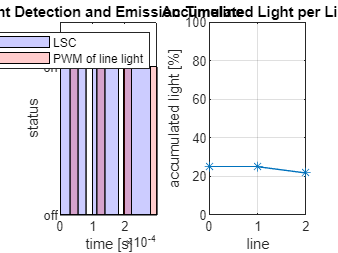

% Plot when LSC has sensor open and when Line light is emmiting light.
subplot(1,2,1)
plot(t, fun_LSC)
hold on
fill_handle_LSC = fill([t fliplr(t)], [fun_LSC zeros(size(fun_LSC))], 'b', 'FaceAlpha', 0.2);
plot(t, fun_line_light)
fill_handle_line_light = fill([t fliplr(t)], [fun_line_light zeros(size(fun_line_light))], 'r', 'FaceAlpha', 0.2);
hold off

title("Light Detection and Emission Timeline")
set(gca, 'ytick', [0 1])
set(gca, 'yticklabel', {'off', 'on'})
xlabel("time [s]")
ylabel("status")
ylim([0, 1.3])
legend([fill_handle_LSC fill_handle_line_light], {'LSC','PWM of line light'},'Location', 'northeast')

% Plot collected light for every frame.
subplot(1,2,2)
plot(0:length(exp_value)-1, exp_value, '*-')

ylim([0, 100])
title("Accumulated Light per Line")
xlabel("line")
%xticks(0:ceil(num_periods/10):num_periods)
ylabel("accumulated light [%]")
grid on